Wrocław 28.04.2021

Aleksander Kudyba   

245084

# Modelowanie złącza p-n w przybliżeniu obszaru całkowicie zubożonego.

Przy pomocy przybliżenia obszaru całkowicie zuborzonego zostały policzone dla złącza p-n w temperaturze 300 K parametry takie jak:

- koncentracja domieszek i ładunek prestrenny wzdłuż złącza;

- pole elektryczne wytworzone w obszarze zuborzonym;

- potencjał pola elektrycznego;

- pasma energetyczne złącza;

W przypadku braku zmian temperatury, stałymi potrzebnymi do obliczeń będą:

- przerwa wzbroniona

close
syms x;
u = symunit;
T = 300;
kB = 8.617*1e-5;
Nd = 8.4e15; %cm-3
Na = 4.8e15; %cm-3
q = 1.602e-19;
Eg(x) = 1.17-4.73*1e-4*x^2/(x+636); %energy centered e.g. equal to zero at Ei
E_g = double(Eg(T)) % eV

E_g = 1.1245

E_c = E_g/2;
Nc(x) = 6.2*1e15*x^(3/2);
N_c = double(Nc(T));
Nv(x) = 3.5*1e15*x^(3/2);
N_v = double(Nv(T));
ni(x) = (Nc(x)*Nv(x))^(1/2)*exp(-Eg(x)/2/kB/x);

- koncentracja samoistna nośników

n_i = double(ni(T)) % cm-3

n_i = 8.6696e+09

% w Ec = 0 z plusem w dół do Ev

- quasi-poziomy fermiego dla typu domieszkowania p i n

Ef_shift_Nd = E_g/2-kB*T*log(Nd/n_i) %przy paśmie Ec typ n (wartość względem Ec)

Ef_shift_Nd = 0.2059

Ef_shift_Na = E_g/2 - kB*T*log(Na/n_i) %przy paśmie Ev typ p (wartość względem Ev)

Ef_shift_Na = 0.2204

Vbi = E_g -(Ef_shift_Na + Ef_shift_Nd);%  Volt
Vbi_test = kB*T*log((Nd*Na)/n_i^2);
eps_Si = 11.7; %F/m 
eps = eps_Si * 8.85417e-12/100; %F/cm
W = sqrt((2*eps/q)*Vbi*(1/Na+1/Nd))*1e4; %micrometers
xn = W * (Na/(Na+Nd));
xp = W * (Nd/(Na+Nd));

## Kierunek zaporowy i przewodzenia:

Vnew =2.2;
V = Vbi + Vnew;
s1 = linspace(-0.5,-xp,1e3);
s2 = linspace(-xp,0,1e3);
s3 = linspace(0,xn,1e3);
s4 = linspace(xn,0.5,1e3);
ss1 = linspace(-1,-xp,1e3);
ss4 = linspace(xn,1,1e3);
dist = [s1 s2 s3 s4];
empty = zeros(1,length(s1));
empty_V = ones(1,length(s1)).*0.6982;
rho_p_area = -q*Na * ones(1, length(s2));
rho_n_area = q*Nd * ones(1, length(s3));
E_p_area = -(q*Na/eps)*(s2+xp)*1e-8;
E_n_area = -(q*Nd/eps)*(xn-s3)*1e-8;
V_p_area = ((q*Na/2/eps)*(s2+xp).^2)/1e8;
V_n_area = ((q*Nd/eps)*(xn-s3/2).*s3 + (q*Na/2/eps)*xp.^2)/1e8;
Ec_p_area = E_g/2 * ones(1,length(ss1));
Ev_p_area = -E_g/2 * ones(1,length(ss1));
Ec_n_area = (E_g/2 - V) * ones(1,length(ss1));
Ev_n_area = -(E_g/2 + V) * ones(1,length(ss1));
Efnew = Ev_p_area + (E_g - Ef_shift_Na);
Efp = Ev_p_area + Ef_shift_Nd;
Efc = Ec_n_area -  Ef_shift_Nd;

%pasma w obszarze zubożonym bez wygładzania (jako prosta linia)
a1 = coeff_a(Ec_p_area,Ec_n_area,-xp,xn);
a2 = coeff_a(Efp,Efc,-xp,xn);
b1 = coeff_b(Ec_p_area,a1,-xp);
b2 = coeff_b(Ev_p_area,a1,-xp);
b3 = coeff_b(Efp,a2,-xp);
func1_p = lin(a1,s2,b1);
func2_p = lin(a1,s2,b2);
func1_n = lin(a1,s3,b1);
func2_n = lin(a1,s3,b2);
func_fermi_p = lin(a2,s2,b3);
func_fermi_n = lin(a2,s3,b3);


## Wykres zależności koncentracji domieszek i ładunku przestrzennego na długości złącza

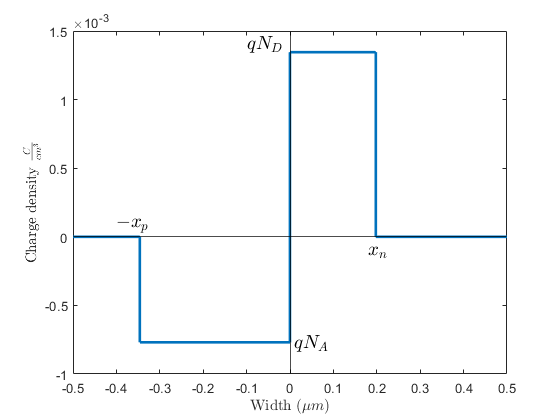

plot([s1  s2  s3 s4], [empty  rho_p_area  rho_n_area empty], "LineWidth", 2)
text(-0.4,0.1e-3,'$-x_p$','Interpreter','latex', 'FontSize', 14)
text(0.18,-0.1e-3,'$x_n$','Interpreter','latex', 'FontSize', 14)
text(-0.1,1.4e-3,'$qN_D$','Interpreter','latex', 'FontSize', 14)
text(0.01,-0.78e-3,'$qN_A$','Interpreter','latex', 'FontSize', 14)
yline(0, 'k')
xline(0, 'k')
xlabel("Width $(\mu m)$",'Interpreter','latex');
ylabel("Charge density $\frac{C}{cm^3}$",'Interpreter','latex');

Ze względu na założenie w przybliżeniu obszaru całkowicie zubożonego, że na granicach obszru zubożonego (-xp, xn) pole elektryczne musi być równe zeru, uzyskujemy dla x = 0 dane wartości pola elektrycznego: przy -xp $\frac{-qN_A}{\varepsilon}x_p$, przy xn $\frac{-qN_D}{\varepsilon}x_n$. Pryzrównując je do siebie otrzymamy warunek $N_Ax_p=N_Dx_n$, czyli zachowanie całkowitego ładunku. Stąd pole pod wykresem dla strony p będzie takie samo jak dla strony n. 

area_p = xp*q*Na

area_p = 2.6606e-04

area_n = xn*q*Nd

area_n = 2.6606e-04

## Wykres zależności pola elektrycznego od głębokości w złączu

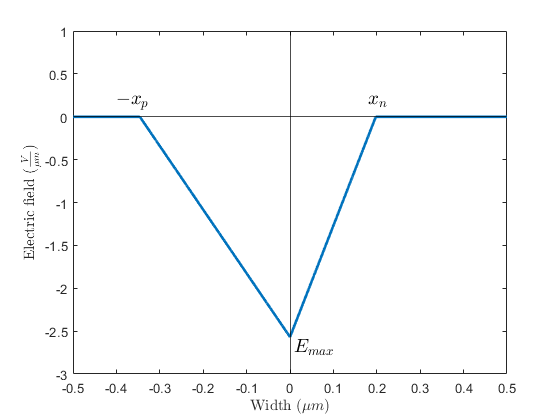

plot([s1  s2  s3 s4], [empty  E_p_area  E_n_area empty], "LineWidth", 2)
yline(0, 'k')
xline(0, 'k')
text(-0.4,0.2,'$-x_p$','Interpreter','latex', 'FontSize', 14)
text(0.18,0.2,'$x_n$','Interpreter','latex', 'FontSize', 14)
text(0.01,-2.7,'$E_{max}$','Interpreter','latex', 'FontSize', 14)
xlabel("Width $(\mu m)$",'Interpreter','latex');
ylabel("Electric field $(\frac{V}{\mu m})$",'Interpreter','latex');
xlim([-0.5 0.5])
ylim([-3 1])

Z przybliżenia obszru całkowicie zuborzonego wynika, że maksiumum pola elektrycznego będzie w miejscu złącza półprzewodników, co rzeczywiście dobrze widać na wykresie. Wynika to wprost z samego warunku, że linie pola elektrycznego muszą by ciągłe wzdłuż złącza. 

## Wykres potencjału w złączu

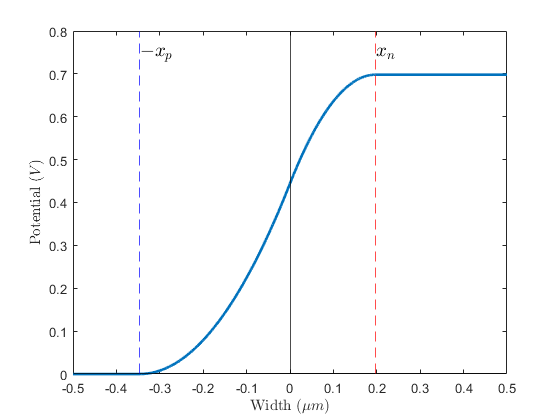

plot([s1 s2 s3 s4], [empty V_p_area V_n_area empty_V], "LineWidth", 2)
yline(0, 'k')
xline(0, 'k')
xlim([-0.5 0.5])
ylim([0 0.8])
xlabel("Width $(\mu m)$",'Interpreter','latex');
ylabel("Potential $(V)$",'Interpreter','latex');
xline(-xp, '--b');
xline(xn, '--r');
text(-xp,0.75,'$-x_p$','Interpreter','latex', 'FontSize', 14)
text(xn,0.75,'$x_n$','Interpreter','latex', 'FontSize', 14)

Chcąc zobrazować różnicę potencjałów na złączu zakładamy, że potencjał po stronie p będzie równy zero, czyli dla x = xp. 

## Diagram pasmowy złącza p-n 

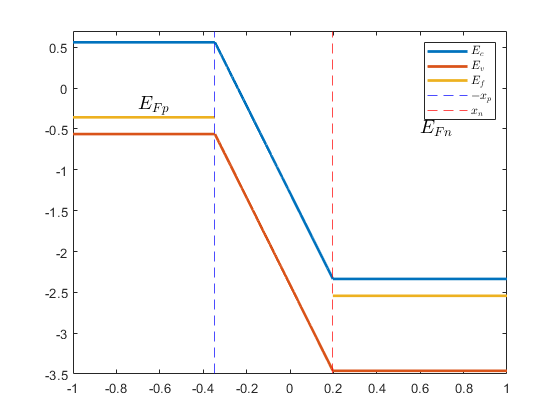

plot([ss1 s2 s3 ss4], [Ec_p_area func1_p func1_n  Ec_n_area], "LineWidth", 2)
xlim([-1 1])
ylim([-3.5 0.7])
hold on
plot([ss1 s2 s3 ss4], [Ev_p_area func2_p func2_n Ev_n_area], "LineWidth", 2)
hold on
 button =0;
if button == 1
    plot([ss1 s2 s3 ss4], [Efp func_fermi_p func_fermi_n Efc], "LineWidth", 2)
xline(-xp, '--b');
xline(xn, '--r');
legend('$E_c$','$E_v$', '$E_f$','$-x_p$', '$x_n$', 'Interpreter', 'latex');
else 
    plot([ss1 NaN s2 s3 NaN ss4], [Efp NaN ones(1,length(s2)) ones(1,length(s3)) NaN Efc], "LineWidth", 2)
xline(-xp, '--b');
xline(xn, '--r');
text(-0.7,-0.2,'$E_{Fp}$','Interpreter','latex', 'FontSize', 14)
text(0.6,-0.5,'$E_{Fn}$','Interpreter','latex', 'FontSize', 14)
legend('$E_c$','$E_v$', '$E_f$','$-x_p$', '$x_n$', 'Interpreter', 'latex');
end



% fileID = fopen('forces.txt','w');
% fprintf(fileID,'%6s %6s  %6s\n','T','x', 'E');
% fprintf(fileID,'%8.4f      %8.4f\n',C);
% fclose(fileID);    


function lin = lin(a, x, b)
lin = a.*x + b;
end
function coeff_a = coeff_a(y1,y2,x1,x2)
coeff_a = (y2 - y1)/(x2-x1);
end
function coeff_b = coeff_b(y1,a,x)
coeff_b = y1 - a.*x; 
end


